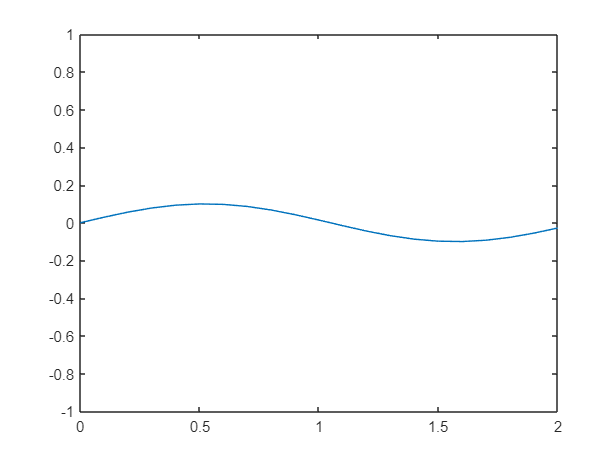

syms omega_1 omega_2 omega_3 r_1 r_2 r_3 v_1 v_2 v_2 T1 T2 T3 H_c1 H_c2 H_c3 H_4

% syms l1 l2 l3 q1 q2 q3 ee

% Contact params
stiffnes = 1000000;
damping = 10;
dyn_fr_coef = 0.3;
st_fr_coef = 0.4;
 
%Gripper
gripper_base = 0.10; % m
gripper_finger_l = 0.07;


StopTime = 20;
b = 0.1;
link_dim = 0.05; %m
pin_r = link_dim/2;
pin_l = link_dim;
l1 = 0.3;
l2 = 0.2;
l3 = 0.3;
ee = gripper_base + gripper_finger_l;
m1 = 0.2;
m2 = 0.4;
m3 = 0.6;
q1 = 0;
q2 = pi/2;
q3 = 0;

h = 0.1;       %m
x_grid = 0 : 0.1 : 2;       %m
y_grid = 0 : 0.1 : 2;       %m
iter = 0 : 20;
grid_median_iter = round(length(x_grid)/2,1,'significant');
surface_formula = h * sin(3*x_grid);
z_heights = zeros(length(x_grid),length(y_grid));
for (i = 1:21)
    z_heights(i,:) = surface_formula(i);
end

plot(x_grid, surface_formula);
% xlim([1.048 1.358])
ylim([-1 1])


omega_1 = [ 0 0 1]';
omega_2 = [1 0 0]';
omega_3 = omega_2;

r_1 = [0; 0; 0];
r_2 =[ 0; 0; l1];
r_3 = [0; l2; l1];



v_1 = -make_skew(omega_1) * r_1;
v_2 = -make_skew(omega_2) * r_2;
v_3 = -make_skew(omega_3) * r_3;
% v_1 = [ 0 0 0 ]';
% v_2 = [ 0 l1 0];
% v_3 = [ 0 l1 -l2]';

T1 = [omega_1; v_1];
T2 = [omega_2; v_2];
T3 = [omega_3; v_3];

c1 = [0; 0; 0.5*l1];
c2 = [ 0; 0.5*l2; l1];
c3 = [0; l2+0.5*l3; l1];
c4 = [0; l2+l3+ee; l1];

H_c1 =[eye(3) c1;
        0 0 0 1];
H_c2 =[eye(3) c2;
        0 0 0 1];
H_c3 =[eye(3) c3;
        0 0 0 1];
H_4 =[eye(3) c4;
        0 0 0 1];

syms R01 R02 R03 q
R = [cos(q) -sin(q) 0; sin(q) cos(q) 0; 0 0 1];
% R01 = eye(3) * subs(R,q,q1);
% R12 = [ 0 0 1;
%         1 0 0;
%         0 1 0] * subs(R,q,q2);
% R23 = eye(3)* subs(R,q,q3);
R01 = eye(3) + sin(q1)*make_skew(omega_1) + (1-cos(q1))*make_skew(omega_1)^2;
R12 = eye(3) + sin(q2)*make_skew(omega_2) + (1-cos(q2))*make_skew(omega_2)^2;
R23 = eye(3) + sin(q3)*make_skew(omega_3) + (1-cos(q3))*make_skew(omega_3)^2;

e1 = [R01 (eye(3)*q1+(1-cos(q1))*make_skew(omega_1) + (q1 - sin(q1)*(make_skew(omega_1)^2)))*v_1
    0 0 0 1];
e2 = [R12 (eye(3)*q2+(1-cos(q2))*make_skew(omega_2) + (q2 - sin(q2)*(make_skew(omega_2)^2)))*v_2;0 0 0 1];
e3 = [R23 (eye(3)*q3+(1-cos(q3))*make_skew(omega_3) + (q3 - sin(q3)*(make_skew(omega_3)^2)))*v_3;0 0 0 1];
H_c1q1q2 = e1 * H_c1;
H_c2q1q2 = e1 *e2* H_c2;
H_c3q1q2q3 = e1 *e2 *e3 * H_c3;
H4_q1q2q3 = e1 * e2 *e3 * H_4;
% simplify(H4_q1q2q3);
double(H4_q1q2q3)

ans =     1.0000         0         0    0.4712
         0    0.0000   -1.0000    0.9425
         0    1.0000    0.0000    1.4412
         0         0         0    1.0000


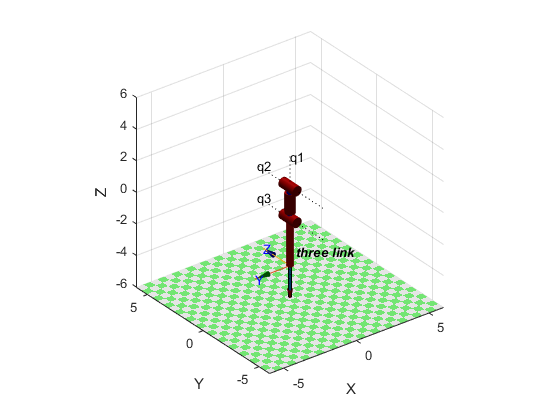

l1 = 1;
l2 = 2;
l3 = 3;

L(1) = Revolute('d', l1, 'a', 0, 'alpha', -pi/2);
L(2) = Revolute('d', 0, 'a', l2, 'alpha', 0);
L(3) = Revolute('d', 0, 'a', l3, 'alpha', 0);
robot = SerialLink(L, 'name', 'three link');
clf
robot.plot([q1,q2,q3],'jaxes');

robot.fkine([q1 q2 q3])

 

ans = 
         0        -1         0         0
         0         0         1         0
        -1         0         0        -4
         0         0         0         1


% px.plot([1 1 0 0], 'jaxes')
% px.edit



function out = make_skew(mat)
    out = [0 -mat(3) mat(2);
            mat(3) 0 -mat(1);
            -mat(2) mat(1) 0];
end